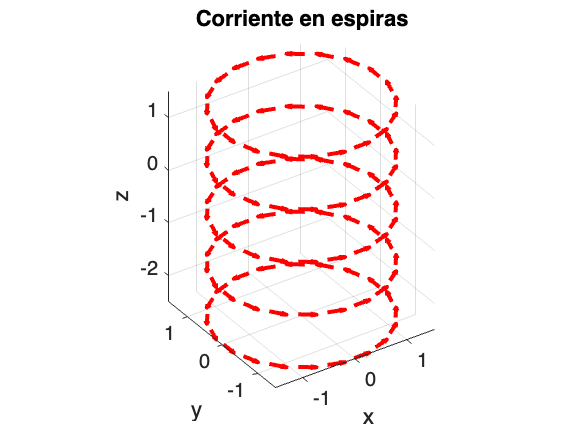

clc;
clearvars;
close all;

nl = 5; % número de espiras
N = 20; % Puntos por espira
R = 1.5; % Radio de cada espira
sz = 1; % Separación entre espiras
I = 300; % Corriente
mo = 4 * pi * 1e-7; % Permeabilidad magnética en el vacío
km = mo * I / (4 * pi); % Constante de Biot-Savart
rw = 0.2; % Grosor efectivo del alambre
plot_option = true;
ds = 0.1;

[Px, Py, Pz, dx, dy, dz] = espiras(nl, N, R);


clf
plot_option = false

plot_option = logical
   0


ds = 0.005

ds = 0.0050

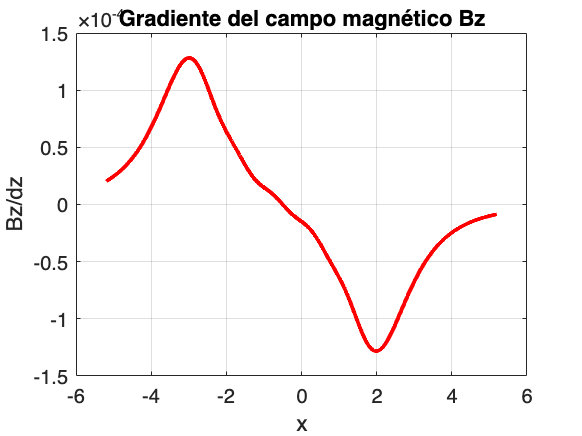

mag = 1000; % Momento magnético (valor moderado)
m = 0.009;
zo = 4.9;
dt = 0.05;
vz_inicial = 0.7;
gamma = 0.08;

[Bz, z] = campoB(ds, km, Px, Py, Pz, dx, dy, nl, N, rw, plot_option);

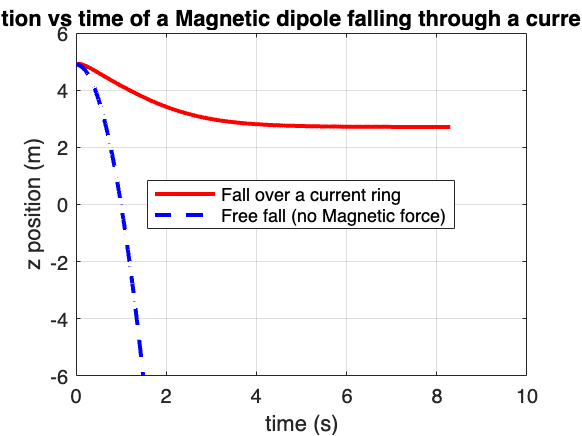


z = trayectoria(Bz, z, mag, m, zo, dt, vz_inicial, gamma);

Animacion

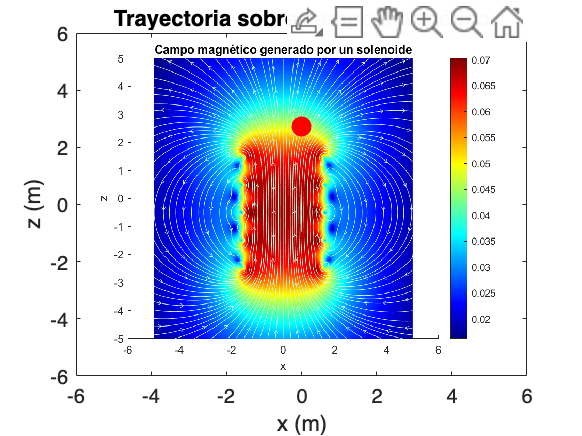

Video guardado como Video


animacion(z, 'campo_magnetico.png', 'Video')